clc; clear;

df = 0.08; rf = df/2;
d_kap = 0.015; rk = d_kap/2;
hf = 0.3;

d_tud = 10e-3;
Atud = (d_tud/2)^2*pi;

Vol = 1.5e-3;

Vv = 0.75e-3;

M = 0.1;

P0 = 5;


g = 9.81;
p2 = P0;


z2 = 3*Vv/(pi*(rf^2+rk^2+rf*rk))

z2 = 0.3661



rho_a = 1.246; % at 10 C
rho_v = 1000;

v1 = sqrt(2*(p2/rho_a + g*z2))

v1 = 3.8998


mdot = v1*rho_v*Atud

mdot = 0.3063

Vv = 0.1e-3:0.01e-3:1.5e-3;

z2 = 3*Vv./(pi*(rf^2+rk^2+rf*rk));
v1 = sqrt(2*(p2/rho_a + g.*z2));

mdot = v1*rho_v*Atud;

mv = Vv*rho_v;
mf = M + mv;

t = mv./mdot;

% syms t mf v1 m_dot

int1 = v1./mdot .* (mf - mdot.*t).*log(mf-mdot.*t) - (mf-mdot.*t) - mf.*log(mf) + mf;
int2 = g*1/2.*t.^2;
int3 = v1.*log(mf).*t;



h_int = int1+int2+int3;


% for i = 1:length(t_slut)
% 
%     % test(:,i) = subs(h_int, [t, mf, v1, mdot], [t_slut(i), mf1(i), v11(i), mdot1(i)]);
%     h1 = subs(int1, [v1, m_dot, mf, t], [v11(i), mdot1(i), mf1(i), t_slut(i)]);
% 
% end
% 
% length(int1)
% length(int2)
% length(int3)


clc; clear;

hf = 0.3;
mf = 0.1; % flaskemasse
Vf = 1.5e-3; % Flaske volumen
d_tud = 10e-3;
Atud = (d_tud/2)^2*pi;

P0 = 5e5; % Starttryk
gamma = 1.4; % cp/cv luft
rho_v = 1000;
rho_a = 1.246;
g = 9.81;

ff = 0.3; % Filling factor
V = 1.5e-3; % Flaske volumen


% Arbejdsligning
flin = 0:0.001:1;

K = @(f) P0.*(1 - f).^gamma.*V.^gamma; % K konstant

W = @(f) K(f).*V.^(-gamma+1)/(-gamma+1) .* (1 - (1 - f).^(-gamma+1)); % Arbejde udført af gas

M_vand = @(f) rho_v*Vf.*f;
M0 = mf + M_vand(flin); % Total masse

W_mass = W(flin)./(mf + M_vand(flin));

% Initial velocity
v1 = @(f) sqrt(2*(P0/rho_v + g*hf.*f))

v1 = function_handle with value:
    @(f)sqrt(2*(P0/rho_v+g*hf.*f))



% Actual velocity
mdot = v1(flin)*rho_v*Atud;

v_ac = -v1(flin)*log((M0 - mdot)/M0)

v_ac =   -8.8596 -99.3459i  -8.8596 -99.3462i  -8.8596 -99.3465i  -8.8597 -99.3468i  -8.8597 -99.3471i  -8.8597 -99.3473i  -8.8597 -99.3476i  -8.8598 -99.3479i  -8.8598 -99.3482i  -8.8598 -99.3485i  -8.8598 -99.3488i  -8.8599 -99.3491i  -8.8599 -99.3494i  -8.8599 -99.3497i  -8.8599 -99.3500i  -8.8600 -99.3503i  -8.8600 -99.3506i  -8.8600 -99.3509i  -8.8601 -99.3511i  -8.8601 -99.3514i  -8.8601 -99.3517i  -8.8601 -99.3520i  -8.8602 -99.3523i  -8.8602 -99.3526i  -8.8602 -99.3529i  -8.8602 -99.3532i  -8.8603 -99.3535i  -8.8603 -99.3538i  -8.8603 -99.3541i  -8.8603 -99.3544i  -8.8604 -99.3547i  -8.8604 -99.3549i  -8.8604 -99.3552i  -8.8604 -99.3555i  -8.8605 -99.3558i  -8.8605 -99.3561i  -8.8605 -99.3564i  -8.8605 -99.3567i  -8.8606 -99.3570i  -8.8606 -99.3573i  -8.8606 -99.3576i  -8.8607 -99.3579i  -8.8607 -99.3582i  -8.8607 -99.3585i  -8.8607 -99.3587i  -8.8608 -99.3590i  -8.8608 -99.3593i  -8.8608 -99.3596i  -8.8608 -99.3599i  -8.8609 -99.3602i


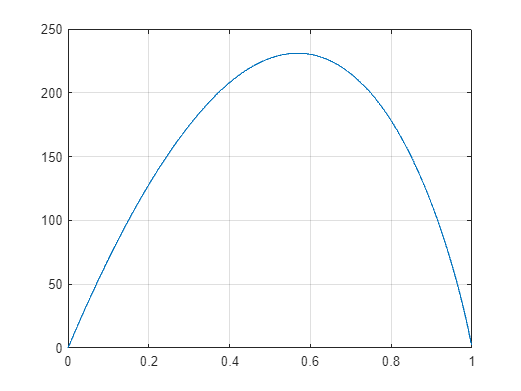


% Den højde flasken når
h = v1(flin).^2/(2*g);


figure
plot(flin, W(flin))
grid

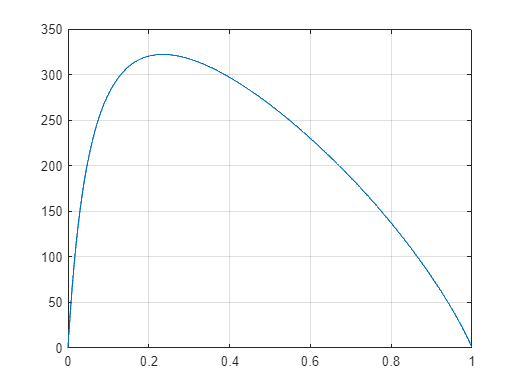


figure
plot(flin, W_mass)
grid

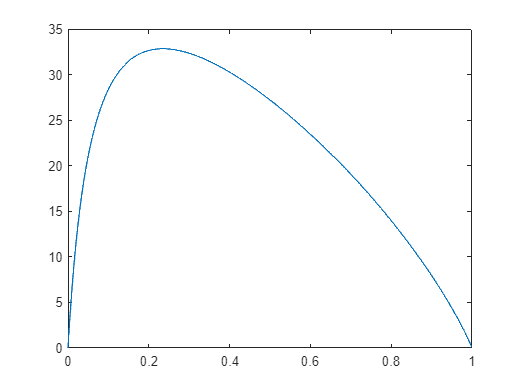


figure
plot(flin, W_mass/g)



[MaxH, MaxHInd]=max(W_mass/g)

MaxH = 32.8333

MaxHInd = 236


flin(MaxHInd)

ans = 0.2350

f_max = flin(MaxHInd);


v1_max = sqrt(2*(P0/rho_v + g*hf*f_max));

m_vand = V*f_max*rho_v;

mdot = v1_max*rho_v*Atud

mdot = 2.4854


t_max = m_vand/mdot

t_max = 0.1418


mf = 0.1 + m_vand

mf = 0.4525


tlin = 0:0.01:20;

v_raket = -v1_max*log((mf - mdot.*t_max)/mf) - g.*t_max

v_raket = 46.3799


a_raket = v1_max*(mf/(mf - mdot*t_max))*mdot-g

a_raket = 346.0743

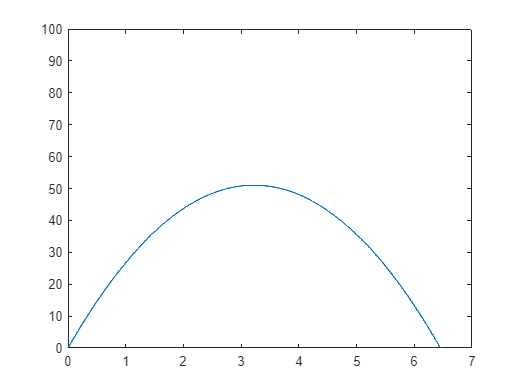



Sted_func = -1/2*g*tlin.^2 + v1_max*tlin;
v_func = -g*tlin + v1_max;

figure
plot(tlin, Sted_func)
ylim([0,100])

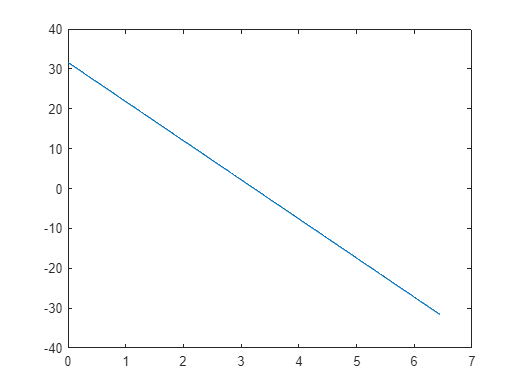


figure
plot(tlin(Sted_func>0), v_func(Sted_func>0))



W_mass(MaxHInd)

ans = 322.0947

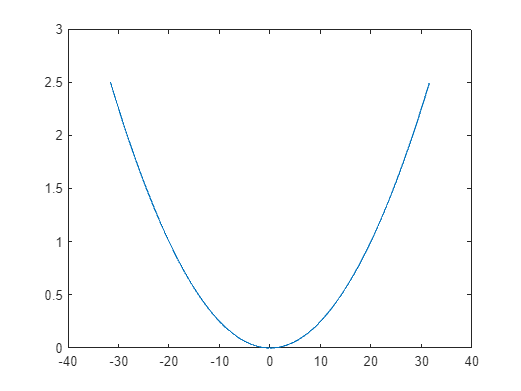



Cd = 0.8;
df = 0.08;
Ap = (df/2)^2*pi;

Fd = Cd*Ap*(rho_a*v_func.^2/2);

plot(v_func(Sted_func>0), Fd(Sted_func>0))